coilsParameters;
salidas=sim('simplePID',['Src' ...

ans = 'xcoilParameters.m'

    'Workspace'],'current');

yout = salidas.get('yout');
t    = salidas.get('tout');
%%%Asign measured values
e=yout(:,1:3); u=yout(:,4:6); y=yout(:,7:9); r=yout(:,10:12);

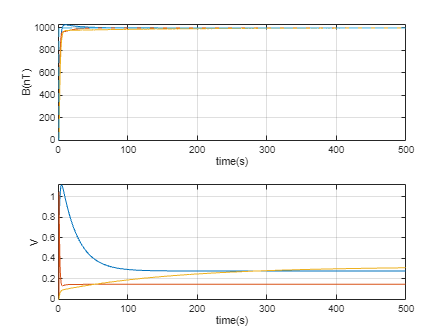

figure()
ax = subplot(2,1,1);
plot(t,y); hold on; grid on;
plot(t,r,'--'); 
xlabel('time(s)'); ylabel('B(nT)');
bx = subplot(2,1,2);
plot(t,u); grid on;
xlabel('time(s)'); ylabel('V');
linkaxes([ax,bx],'x');